clear all;

speed1= 20/3.6; % from 1st gear to 2nd gear
speed2= 35/3.6; % switch off throttle
f_max= 1090;

v1= 0:0.1:speed1;
f1= ones(1, length(v1))+ rand(1, length(v1)).*0.05;

v2= speed1*ones(1, length(v1));
n= (1-0.5)/length(v2);
range= [0.5:n:1];
f2= range + rand(1,length(range)).*0.05;
f2= flip(f2(1:end-1));
f2= [f1(end), f2(2:end)];

v3= speed1:0.1:speed2;
f3= 0.5*ones(1, length(v3))+ rand(1, length(v3)).*0.025;
f3= [f2(end), f3(2:end)];

v4= speed2*ones(1, length(v3));
n= 0.5/length(v4);
range= [0.0:n:0.5];
f4= range + rand(1,length(range)).*0.025;
f4= flip(f4(1:end-1));
f4= [f3(end), f4(2:end-1), 0];

v5= speed2:0.1:(speed2+10);
f5= zeros(1,length(v5));


v= [v1, v2, v3, v4, v5];
f= [f1, f2, f3, f4, f5]*f_max;

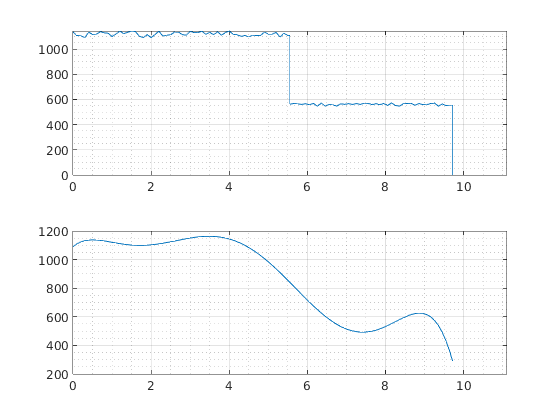

[p]= polyfit(v,f,6);

y= polyval(p, v);

close all;
figure();
subplot(2,1,1)
plot(v,f);
grid on; grid minor;
xlim([0,40/3.6]);

subplot(2,1,2)
plot(v,y);
grid on; grid minor;
xlim([0,40/3.6]);